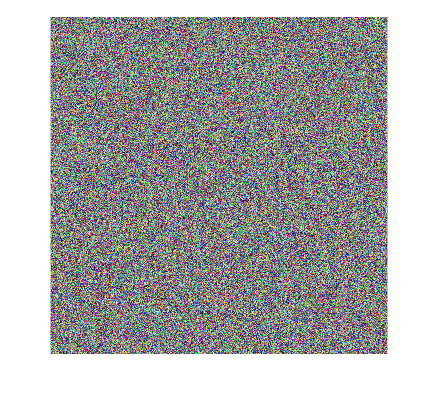

img = imread("squaredog.jpg");

type = 'gauss';
alpha = 20000;
%% Generazione spostamenti casuali
dx = -1+2*rand(size(img));
dy = -1+2*rand(size(img));

imshow(rescale(dx,0,1))

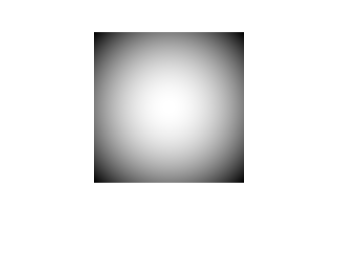


%% Creazione filtro
if strcmp(type,'gauss')
    H = fspecial('gauss',[150, 150], 900); % crea un filtro gaussiano
elseif strcmp(type,'average')
    H = fspecial('average',[150, 150]); % crea un filtro mediano
elseif strcmp(type,'disk')
    H = fspecial('disk',80); % crea un filtro mediano circolare
elseif strcmp(type,'log')
    H = fspecial('log',[150, 150], 3); % crea un filtro combinando un laplaciano e un gaussiano
elseif strcmp(type,'motion')
    H = fspecial('motion', 900, 240); % crea un filtro che simula il movimento di una telecamera
end

%H = (1:150)/2/pi;
%H = sin(H.')*cos(H)/10000;

imshow(rescale(H,0,1))

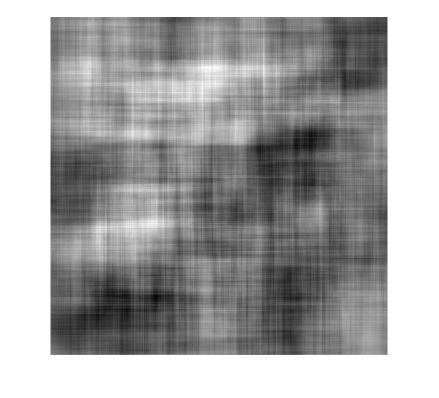


% applico il filtro agli spostamenti
fdx = conv2(dx(:,:,1),H,'same');
fdy = conv2(dy(:,:,1),H,'same');

imshow(rescale(fdx,0,1));

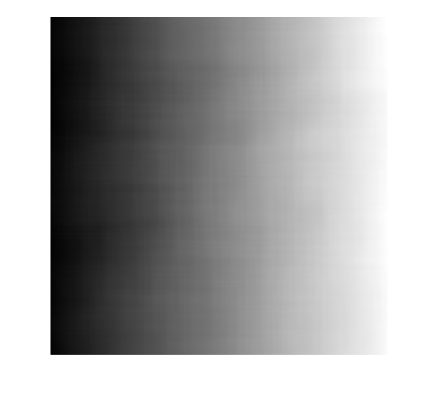


% normalizzo
n=sum((fdx(:).^2+fdy(:).^2));
fdx=alpha*fdx./n;
fdy=alpha*fdy./n;
%creo una griglia con gli indici della matrice
[y, x]=ndgrid(1:size(img,1),1:size(img,2));

imshow(rescale(x-fdx(:,:,1),0,1));

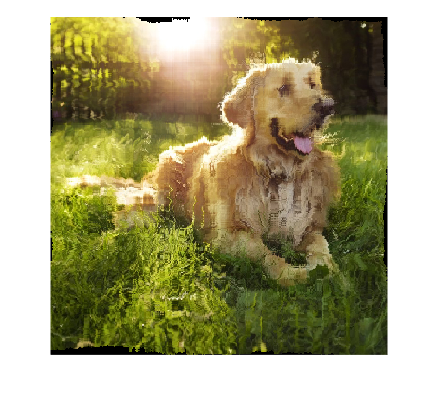


%% Interpolazione
R = interp2(double(img(:,:,1)),x-fdx(:,:,1),y-fdy(:,:,1));
R(isnan(R))=0;
G = interp2(double(img(:,:,2)),x-fdx(:,:,1),y-fdy(:,:,1));
G(isnan(G))=0;
B = interp2(double(img(:,:,3)),x-fdx(:,:,1),y-fdy(:,:,1));
B(isnan(B))=0;


%% Conversione in rgb
imshow(uint8(cat(3, R, G, B)));